clear all;
clc;
close all;
disp('Iris Eting 209027333')

Iris Eting 209027333


disp('Nadav Orenstein 312349509')

Nadav Orenstein 312349509


## 1 Edge Detection

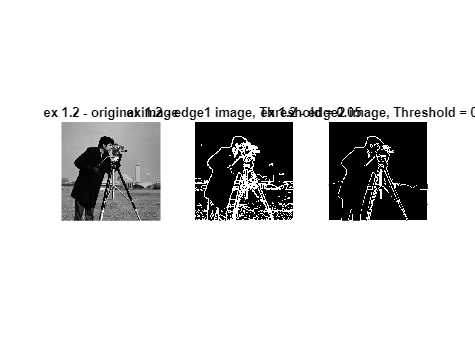

%%%%% 1 Edge Detection %%%%%%%
%1.1 Reading the Image
cameraman = imread_normalized_1("cameraman.tif");

%1.2 Prewitt Edge Detector
edge1 = dip_prewitt_edge(cameraman,0.05);
edge2 = dip_prewitt_edge(cameraman,0.15);

%% Display
fig = figure();
subplot(1,3,1);
imshow(cameraman);
title('ex 1.2 - original image');
subplot(1,3,2);
imshow(edge1);
title('ex 1.2 - edge1 image, Threshold = 0.05');
subplot(1,3,3);
imshow(edge2);
title('ex 1.2 - edge2 image, Threshold = 0.15');
saveas(fig,'ex 1.2.jpeg');

## 1.3 Canny Edge Detector

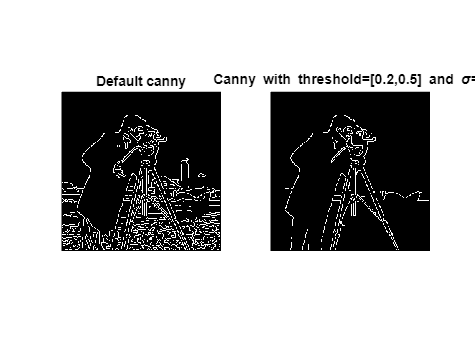

% 1.3 Canny Edge Detector
fig = figure();
subplot(1,2,1);
edge(cameraman,'canny');
title('Default canny');
subplot(1,2,2);
edge(cameraman,'canny',[0.2,0.5],1);
title('Canny with threshold=[0.2,0.5] and \sigma=1')
saveas(fig,'ex 1.3.2.jpeg');

# 2.1 Hough line Transform 

#### (a) Read the floor.jpg image, convert into grayscale image and normalize.

floor = imread_normalized("floor.jpg");

#### (b) Extract the edges using MATLAB’s edge()

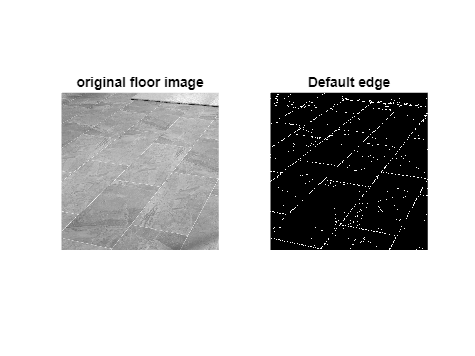

[BW,TH]=edge(floor);
% Display
fig = figure();
subplot(1,2,1);
imshow(floor);
title('original floor image');
subplot(1,2,2);
imshow(BW);
title('Default edge');
saveas(fig,'ex 2.1.b.jpeg');

TH

TH = 0.0565

#### (c) Writing our own dip_hough_lines

hough_matrix_1 = dip_hough_lines(BW, 1, 1);

hough_matrix_2 = dip_hough_lines(BW, 5, 4);

(d) displaying the Hough Matrix

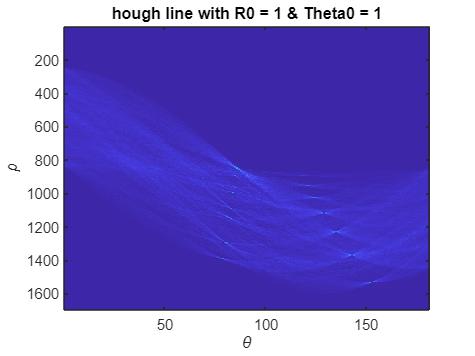

figure;  imagesc(hough_matrix_1); title("hough line with R0 = 1 & Theta0 = 1");
xlabel('\theta');
ylabel('\rho');

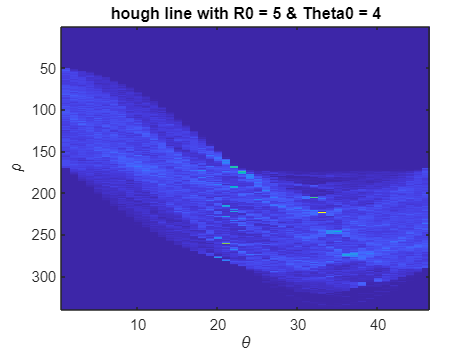

figure; imagesc(hough_matrix_2); title("hough line with R0 = 5 & Theta0 = 4");
xlabel('\theta');
ylabel('\rho');

## Using imshow(M,[]) did work but less visible for us that's why we used imgsec

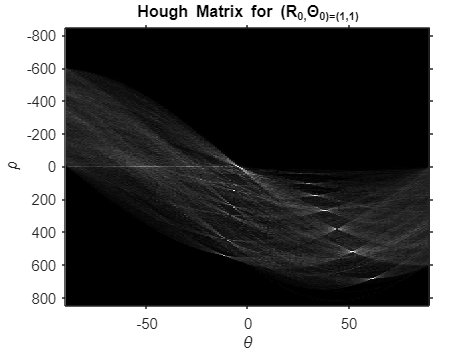

%
[M,N]=size(BW);
R1=fix(-sqrt(M^2+N^2):1:sqrt(M^2+N^2));
theta1=fix(-90:1:90);
figure;
imshow(gray2ind(hough_matrix_1,3),[],'XData',theta1,'YData',R1,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal;
axis([-90 90 -sqrt(M^2+N^2) sqrt(M^2+N^2)])
title('Hough Matrix for (R_0,\Theta_0)=(1,1)');

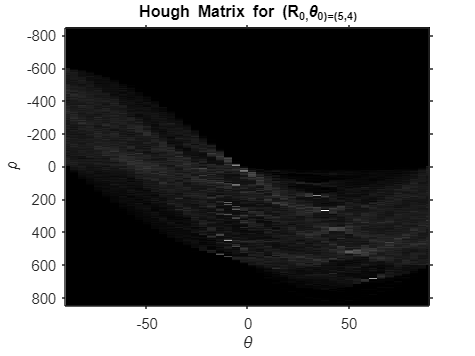

figure;
R5=-sqrt(M^2+N^2):5:sqrt(M^2+N^2);
theta4=-90:4:90;
imshow(hough_matrix_2,[],'XData',theta4,'YData',R5,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal;
axis([-90 90 -sqrt(M^2+N^2) sqrt(M^2+N^2)])
title('Hough Matrix for (R_0,\theta_0)=(5,4)');

disp("hi")

hi


%

#### (e) Find the 4 most significant lines in the BW image, and plot them on the grayscale floor image

peaks= houghpeaks(hough_matrix_1,4);
peaks(:,1) = R1(peaks(:,1));
peaks(:,2) = theta1(peaks(:,2));


peaks

peaks =    380    44
   520    52
     0    -5
   268    38




peaks

peaks =    380    44
   520    52
     0    -5
   268    38


disp("hi nadav")

hi nadav


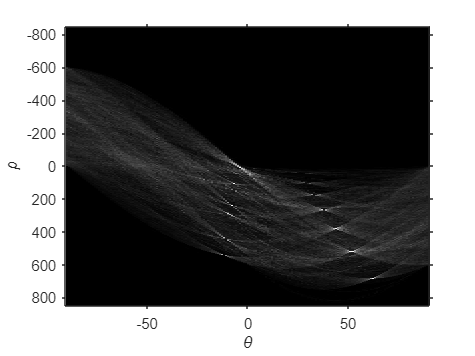

figure;

imshow(gray2ind(hough_matrix_1,3),[],'XData',theta1,'YData',R1,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
hold on;
axis on, axis normal;

hold off;

# 2.2 Hough circle Transform 

#### (a) read the coffee.png image, converted it into grayscale image and normalized

coffee = imread_normalized("coffee.jpg");


#### (b) Extract the edges using MATLAB’s BW=edge(I).

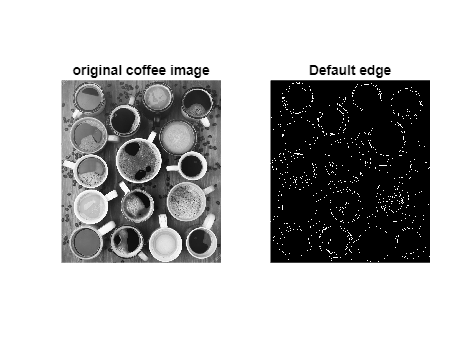

[BW2,TH2]=edge(coffee);
% Display
fig = figure();
subplot(1,2,1);
imshow(coffee);
title('original coffee image');
subplot(1,2,2);
imshow(BW2);
title('Default edge');
saveas(fig,'ex 2.1.b.jpeg');

TH2

TH2 = 0.1105

#### (c) Write your own dip_hough_circlesfunction that calculates the Hough Matrix

we wrote our own function 

#### (d) Measure the Run-Time of your function

tic;
H_circles_1 = dip_hough_circles(BW2, 1, 1);
toc;

Elapsed time is 10.462547 seconds.


tic;
H_circles_2 = dip_hough_circles(BW2, 4, 10);
toc;

Elapsed time is 0.391829 seconds.


tic;
H_circles_speedup =dip_hough_circles(BW2, 20, 1);
toc;

Elapsed time is 0.584438 seconds.


#### (e)display one slice (2D image) using imshow(M,[])

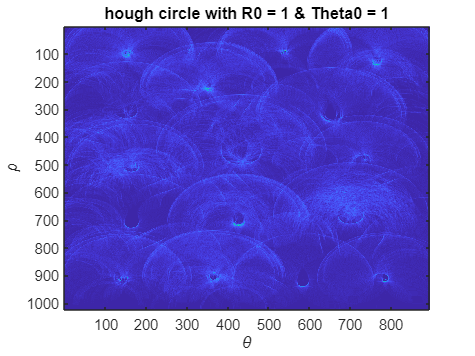


figure;  imagesc(H_circles_1(:,:,1)); title("hough circle with R0 = 1 & Theta0 = 1");
xlabel('\theta');
ylabel('\rho');

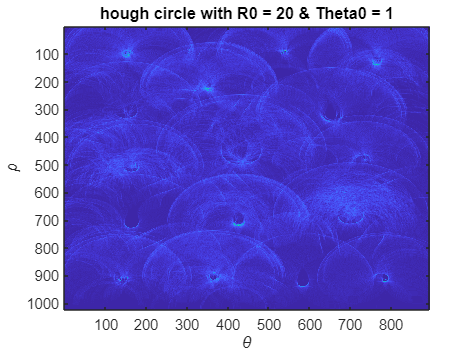

figure;  imagesc(H_circles_speedup(:,:,1)); title("hough circle with R0 = 20 & Theta0 = 1");
xlabel('\theta');
ylabel('\rho');

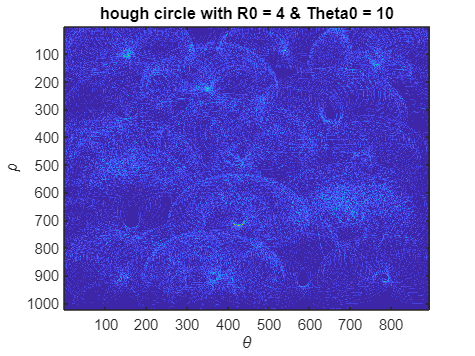


figure;  imagesc(H_circles_2(:,:,1)); title("hough circle with R0 = 4 & Theta0 = 10");
xlabel('\theta');
ylabel('\rho');

#### (f) Write you own dip_houghpeaks3d

peaks3d = dip_houghpeaks3d(H_circles_1)

peaks3d =    915   785     8
   705   427    14
   712   163    17
   483   737     1
   125   765     4


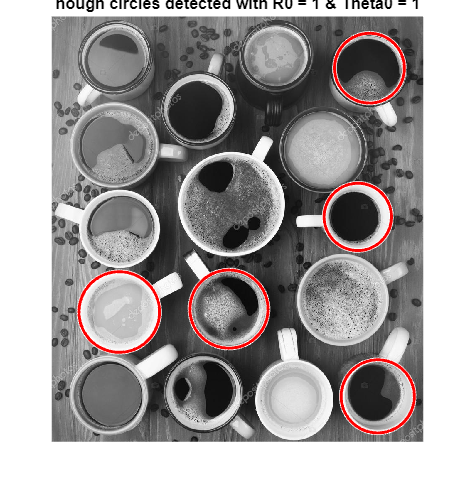

Rmin = 80;
% get the circle params from the result
xy = peaks3d(:,2:-1:1);
r = Rmin + peaks3d(:,3);

imshow(coffee);title("hough circles detected with R0 = 1 & Theta0 = 1"); viscircles(xy,r);

peaks3d = dip_houghpeaks3d(H_circles_2)

peaks3d =     97   149     2
   217   351     3
   904   367     4
   100   149     2
   483   737     1


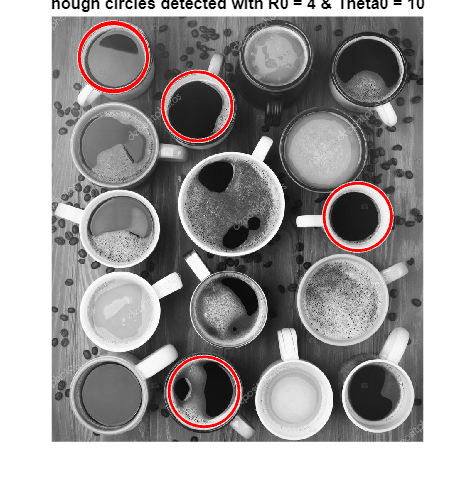

Rmin = 80;
% get the circle params from the result
xy = peaks3d(:,2:-1:1);
r = Rmin + peaks3d(:,3);

imshow(coffee);title("hough circles detected with R0 = 4 & Theta0 = 10"); viscircles(xy,r);

peaks3d = dip_houghpeaks3d(H_circles_speedup)

peaks3d =    483   737     1
   708   162     2
   103   147     1
    88   539     1
   101   148     1


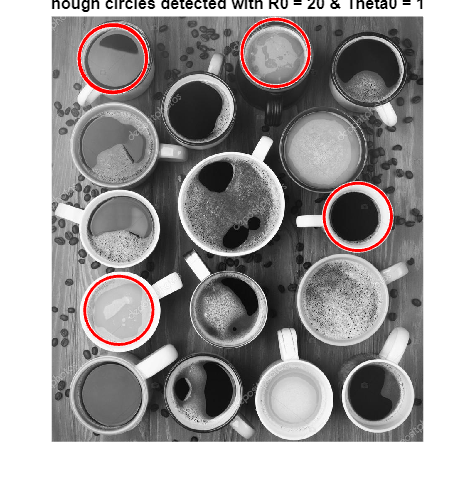

Rmin = 80;
% get the circle params from the result
xy = peaks3d(:,2:-1:1);
r = Rmin + peaks3d(:,3);

imshow(coffee);title("hough circles detected with R0 = 20 & Theta0 = 1"); viscircles(xy,r);